# ME:6240 Short Homework #4

Due: 4/7/2021

#### Particle Filter Primer

## Michael Swafford

#### Consider an airplane that can only move in one dimension (forward and backward). Assume that the airplane is moving in the forward direction at a known constant velocity. Let's say that we have an initial belief for the location of the airplane taking the following analytical form,

#### 
$$bel(x)=\frac{1}{5.75}exp(\frac{-x^2}{2})[sin^2(x+6)+3cos^2(x)sin^2(4x)+1]$$


#### which has a base of support $\epsilon [-4,4]$. Let's say we want to perform a simple Monte Carlo simulation using samples from this belief distribtuion (target distribution). Even though we have an analytical form for the target distribtuion, it is not actually possible to sample from it directly. Instead we are going to use a uniform distribtion as a proposal distribution.

# 1) Using important sampling, generate N=800 particles with appropriate weights from the target distribution described above. Probide a plot of the analytical form of the target distribution over its base of support along with the particles and their corresponding weights. (Equation 1.14 from 4/1 reading and MATLAB stem funtion will be useful)

#### Eqn 1.14 $w^{[i]}_t = \eta\frac{p(x^{[i]}_t)}{\pi(x^{[i]}_t)}$

clear all

%setup domain
N = 800;
X = zeros([2,N]);
%analytical proposed
prop = 1/8*ones(1,N);
%sum(prop) %verifying uniform sol sums to 1
%generate a matrix of weights, row 1 is the domain location, row 2 is the
%weight value  
X(1,:) =-4 + (4+4)*rand(N,1);
for i = 1:N
    X(2,i) = 1/5.75*exp(-(X(1,i)^2)/2)*((sin(X(1,i)+6))^2+3*(cos(X(1,i)))^2*(sin(4*X(1,i)))^2+1);
    X(2,i) = X(2,i)/prop(i);
end
eta = sum(X(2,:));
X(2,:) = X(2,:)./eta;
sum(X(2,:)) %verify sum to one

ans = 1.0000

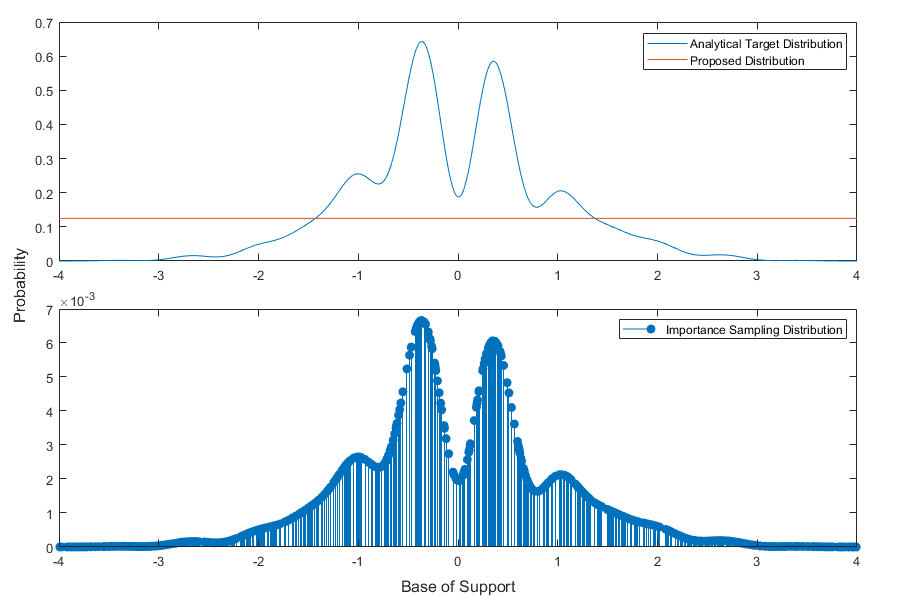

%analytical bel
num_x = linspace(-4,4,N);
bel = (1./5.75).*exp(-(num_x.^2)./2).*((sin(num_x+6)).^2+3.*(cos(num_x)).^2.*(sin(4.*num_x)).^2+1);
%a = cumtrapz(num_x,bel)
%a(end)


figure("Position",[10 10 900 600])
t=tiledlayout(2,1);
t.TileSpacing = 'compact';
t.Padding = 'compact';
ax1=nexttile;
plot(ax1,num_x,bel)
hold on
plot(ax1,num_x,prop)
hold off
legend(["Analytical Target Distribution","Proposed Distribution"])
%plot weights
ax2=nexttile;
stem(ax2,X(1,:),X(2,:),"filled")
xlabel(t,"Base of Support")
ylabel(t,"Probability")
legend(["Importance Sampling Distribution"])

# 2) Implement the resampling algorithm from reading (Algo 1.2) and explain what the algorithm is doing *In your own words.* Now, run the particles and weights from the previous question through the algorithm. Provide a plot of the analytical form of the target dsitribution over its base of support along with the new particles and their corresponding new wieghts. Comment on how the distribution of particles has changed from the previous question to this one.

#### Algorithm 1.2 The low-variance resampling algorithm

### Input: Weighted sample set

#### S_t = 0

#### r = rand_uniform((0;1/N))

#### 
$$c = \hat w_t^{[1]}$$


#### i = 1

#### for n = 1 to N do

####     U = r+(n-1)/N

####     while U > c

####         i=i+1

####         c=c+$\hat w_t^{[i]}
$

####     end

####     S_t = S_t U {<x,1/N>}

#### end

#### return S_t

## Algorithm searches through the weights for values that are greater than the CDF of the uniform function and adds the weight to a new vector S_t.

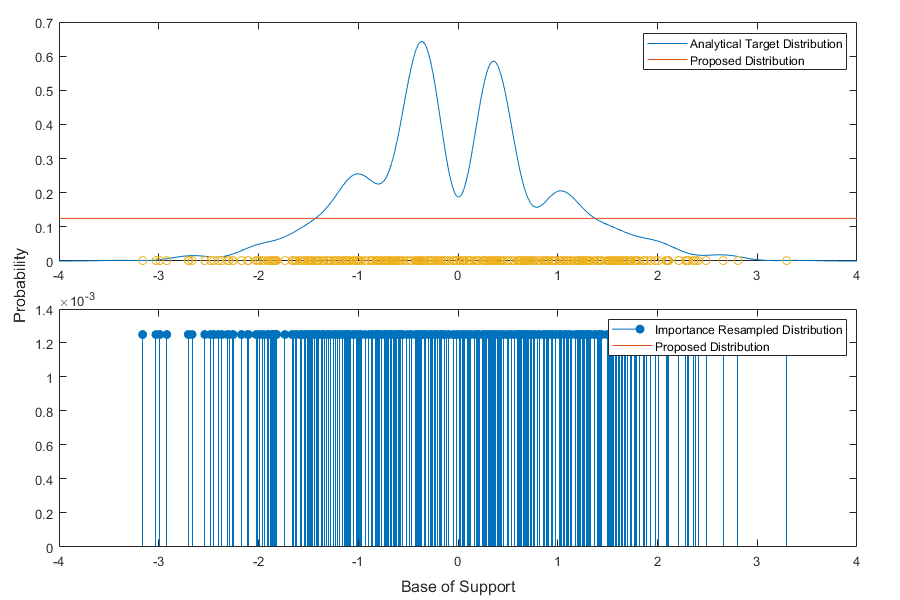


S = zeros(N,2); %add resampling col
r = rand(1);
r = r./N;
c = X(2,1);
i = 1;
for n=1:N
    U = r+(n-1)/N;
    while U > c && i<800
        i = i + 1;
        c = c + X(2,i);
    end
    S(n,1) = X(1,i); %add large weight to resample particle
end
%sort S
S = sortrows(S);
sNew = S;
sNew(:,2) = 1/N;


figure("Position",[10 10 900 600])
t=tiledlayout(2,1);
t.TileSpacing = 'compact';
t.Padding = 'compact';
ax1=nexttile;
plot(ax1,num_x,bel)
hold on
plot(ax1,num_x,prop)
stem(ax1,sNew(:,1),sNew(:,2))
hold off
legend(["Analytical Target Distribution","Proposed Distribution"])
%plot weights
ax2=nexttile;
stem(ax2,sNew(:,1),sNew(:,2),"filled")
hold on
plot(ax2,num_x,r)
xlabel(t,"Base of Support")
ylabel(t,"Probability")
legend(["Importance Resampled Distribution","Proposed Distribution"])

##  Particles are more densly clustered where high probabilities in the target distribution are present. All particles have the same weight =  1/N 

# 3) Propagate each particle through the following process model for 5 seconds with a time step of 0.1 sec,

# 
$$x_{k+1} = x_k + s_0\delta t+w_k$$


# where $s_0=10 m/s,\delta t =0.1 sec$, and $w_k\sim\mathcal{N}(0,2)$. For every time step, you will need to generate a new vector, $w_k \in \mathbb{R}^N$, from the aforementioned normal distribution governing the process noise. Provide a single plot of the trajectories for each initial sample (w/labels and units).

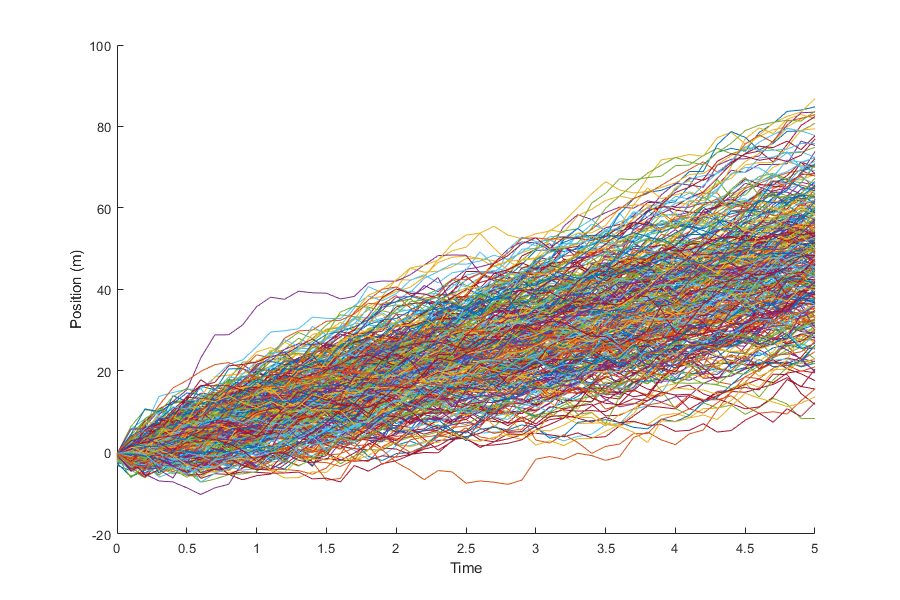

s0 = 10;
deltaT = 0.1;
t = 0:deltaT:5;
mu = 0;
sigma = 2;
state = zeros(N,length(t));
state(:,1) = sNew(:,1); %put in initial particles
for i=1:length(t)
    w = normrnd(mu,sigma,[N,1]); %generate a new noise vecotr
    state(:,i+1) = state(:,i)+s0*deltaT+w;
end
state(:,end)=[];

%%%%%
sUnique = unique(sNew);
L = length(sUnique);
uniqueState = zeros(L,length(t));
uniqueState(:,1)=sUnique(:,1);
for i=1:length(t)
    w = normrnd(mu,sigma,[L,1]); %generate a new noise vecotr
    uniqueState(:,i+1) = uniqueState(:,i)+s0*deltaT+w;
end
uniqueState(:,end)=[];
figure("Position",[10 10 900 600])
%plot trajectories from process model
hold on
for n=1:L
    plot(t,state(n,:))
end
hold off
xlabel("Time")
ylabel("Position (m)")

# 4) Now, let's say at the end of the 5 seconds, a direct measurement of the airplanes position, $z_m = 50m$, becomes available with the following observation model,

# 
$$\hat z=x+v$$


# where $v\sim\mathcal{N}(0,10)$. Use this measurement model to calculate innovations to update the weights of the particles and provide a plot of the particles and their corresponding weights. (Use the normpdf function to calculate the probabilities of the innovations.) Run the particles (and weights) through the resampling algorithm and provide a plot of the particles and their updated weights. Comment on how the distribution has changed as a results of the resampling. 

### 
$$\mathcal{I}=z_m - \hat z$$


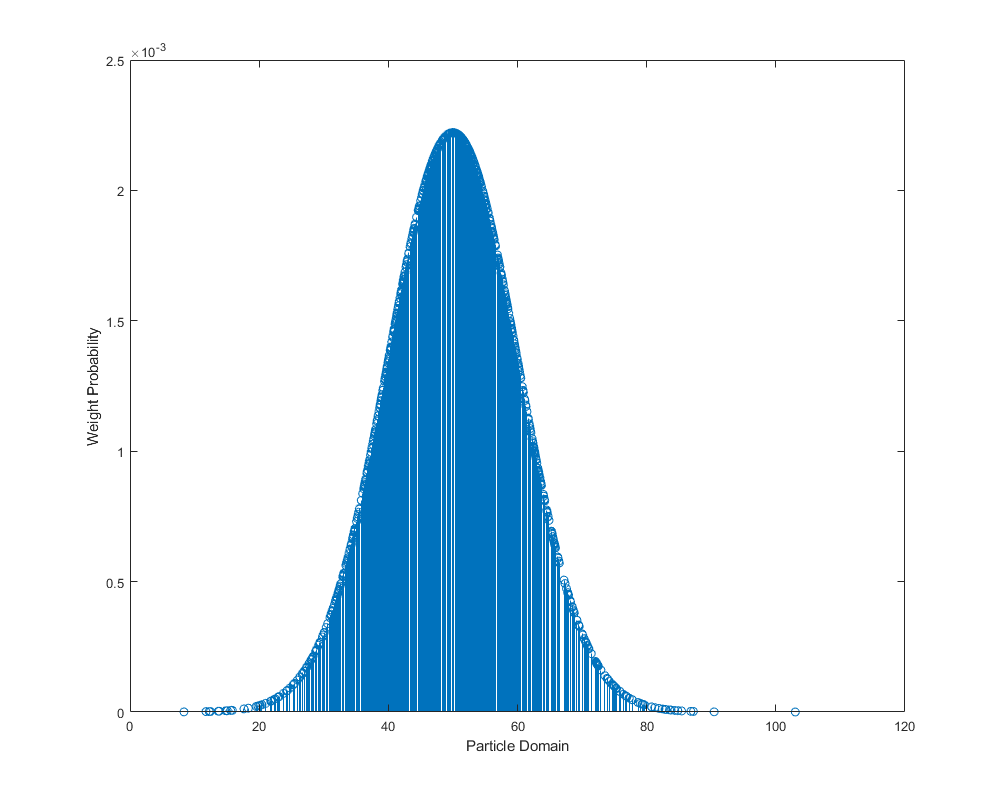

zm = 50;
zhat = zeros(N,1);
Inn = zeros(N,1);
sigma2 = 10;
for n=1:N
    %v = normrnd(mu,sigma2); %generate a new noise vector
    zhat(n,1) = state(n,end);%+v; %predict a measurement 
end
%calculate innovation between true and expected measurement
Inn = zm-zhat;
w = normpdf(Inn,mu,sigma2); %find probability of innovations
w = w.*sNew(:,2);
w=w./sum(w);
figure("Position",[12 12 1000 800])
stem(state(:,end),w)
xlabel("Particle Domain")
ylabel("Weight Probability")


S2 = zeros(N,1); %add resampling col
r = rand(1);
r = r./N

r = 8.6902e-04

c = w(1);
i = 1;
for n=1:N
    U = r+(n-1)/N;
    while U > c && i<N
        i = i + 1;
        c = c + w(i);
    end
    S2(n,1) = state(i,end); %add large weight to resample particle
end
%sort S2
S2 = sortrows(S2);
s2New = S2;
uniqueParticles = unique(S2);
numUnique = length(uniqueParticles)

numUnique = 592

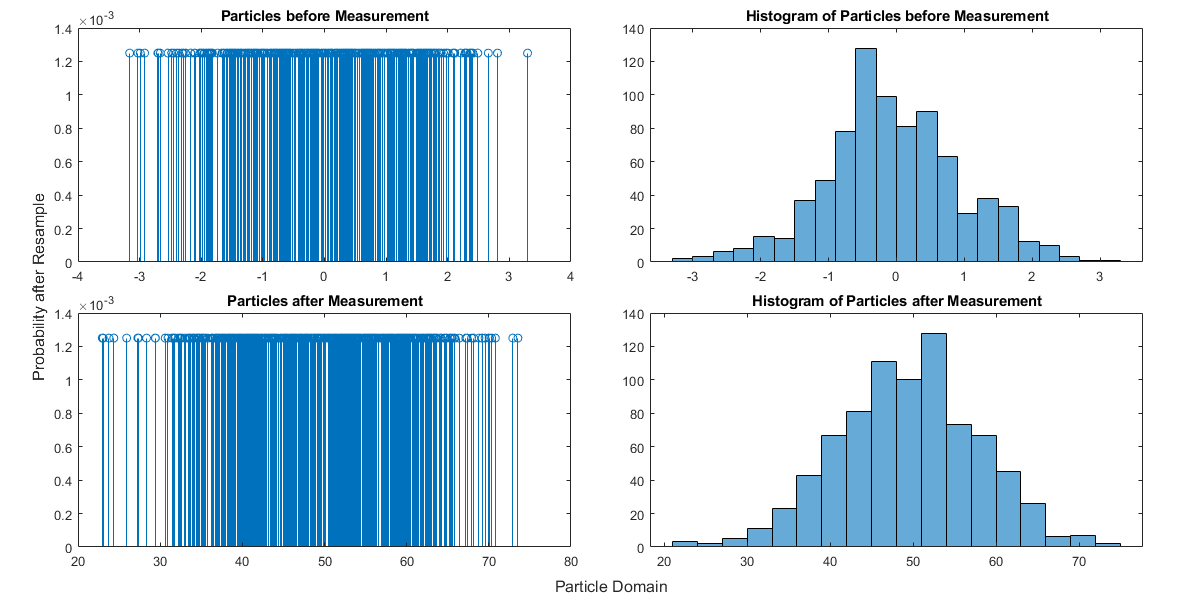

s2New(:,2) = 1/N;


figure("Position",[10 10 1200 600])
t2 = tiledlayout(2,2);
t2.TileSpacing = "compact";
t2.Padding="compact";
ax1 = nexttile;
stem(ax1,sNew(:,1),sNew(:,2))
title(ax1,"Particles before Measurement")
ax2 = nexttile;
h1 = histogram(sNew(:,1));
title(ax2,"Histogram of Particles before Measurement")
ax3 = nexttile;
stem(ax3,s2New(:,1),s2New(:,2))
title(ax3,"Particles after Measurement")
xlabel(t2,"Particle Domain")
ylabel(t2,"Probability after Resample")
ax4 = nexttile;
h2 = histogram(s2New(:,1));
title(ax4,"Histogram of Particles after Measurement")

## Distribution of particles after resampling changes to gaussian from the target distribution. The number of unique points is significantly reduced as can be seen by areas of higher density (stem grouping).

# 5)  Find two research articles that are pertinent to your final project. They can describethe mechanical system,a process model, a measurement model, an algorithm, etc. Describe what and how the information in the papers are useful to you in your final project. 

- RadarSLAM: Radar Lased Large-Scale Slam in All Weathers [https://arxiv.org/pdf/2005.02198.pdf](https://arxiv.org/pdf/2005.02198.pdf)

- Real-Time Pose Graph SLAM based on Radar [https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=8813841](https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=8813841)

## In [1] the concept of Radar based SLAM is introduced, they use a 360 deg scan from a FMCW type radar. System process model is described as well as an algorithm for converting from Radar scan to point cloud type data. A method for data association is also well defined. Authors clearly denote what other available algorthims they are employing to make their entire system work.

## In [2] they use a similar approach to that of [1], however, they limit themselves to 1 forward facing radar to construct their map. They use odometry to improve their estimations and optionally can use GNSS to provide further certainty of the final pose estimation. The author's provide a grate process diagram to understand the data pipeline shown below. The paper also presents the measurement model used to update an UKF for the odometry portion of the pose estimate. The authors in [2] use the Iterative Closest Point (ICP) method for data association of radar scans.